#   ECSE 343: Numerical Methods in Engineering

#  Assignment 3

Due Date: 23rd March 2021

Student Name: Linwei Yuan

Student ID: 260857954

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

Note: You can write the function in the appendix section using the provided stencils.

**Question 1: **

**a) **For two given matrices $A,B\in \Re^{\;N\times N} \;\ldotp$ Is $e^{\mathit{\mathbf{A}}} \ldotp e^{\mathit{\mathbf{B}}} =e^{\mathit{\mathbf{A}}+B} ?\;$Explain.

see PDF

**b)  **Under what condition is $e^{\mathit{\mathbf{A}}} \ldotp e^{\mathit{\mathbf{B}}} =e^{\mathit{\mathbf{A}}+B} \;$? Elaborate.

see PDF

**Question 2:  Eigenvalues!**

a) The Power Iteration method is used to compute the dominant eigen value  and the  eigen vector associated with the  dominant eigen value of a given matrix. Any random vector $x_0$ can be written as the linear combination of $n$ independent eigen vectors of a matrix ${\mathit{\mathbf{A}}}_{n\times n}$ as 


$${\mathit{\mathbf{x}}}_{0\;} =c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\mathit{\mathbf{v}}}_2 +\cdots +c_n {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;} \;\;\;$$
                                             
$$\left(1\right)$$


On multiplying the above with matrix $\mathit{\mathbf{A}}$ we get,


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\mathit{\mathbf{A}}\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;}$$
                                  
$$\left(2\right)$$


The vectors ${\mathit{\mathbf{v}}}_i$'s are the eigen vectors of matrix $\mathit{\mathbf{A}}$, therefore, $\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}} =\lambda_{i\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$. The symbol  $\lambda_{i\;}$denotes the eigen value corresponding to eigen vector ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$.  


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;} \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                                
$$\left(3\right)$$


Equation (3), can be  generalised to 


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;}^{k\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;}^k \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;}^{k\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                              
$$\left(4\right)$$


Without loss of generality (4) can be written as


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =\lambda_{1\;}^{k\;} \left(c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\frac{\lambda_{2\;}^k }{\lambda_{1\;}^{k\;} }\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \frac{\lambda_{n\;}^{k\;} }{\lambda_{1\;}^{k\;} }{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;} \right)$$
                     
$$\left(5\right)$$


Assuming that $\left|\lambda {\;}_1 \right|>$$\left|\lambda_2 \right|>\cdots \left|\lambda_n \right|$.  As $k\to \infty$, the terms with  $\frac{\lambda_{j\;}^k }{\lambda_{1\;}^{k\;} }\to 0$.  Thus, as $k\to \infty$,  ${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;}$converges to the eigen vector ${\mathit{\mathbf{v}}}_{1\;}$ corresponding to the largest eigen value. Write an iterative algorithm which computes the eigen vector and eigen value using the following recurssive formula,


$${\mathit{\mathbf{v}}}^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel }$$
                                                                   
$$\left(6\right)$$
   

where ${\mathit{\mathbf{v}}}^{\left(k+1\right)}$ is the eigen vector at ${\left(k+1\right)}^{\textrm{th}}$iteration.

 Stop the algorithm using when the $\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel \;<\epsilon_{\textrm{tol}}$, where $\epsilon_{\textrm{tol}}$ is the input tolerance value. 

Write a MATLAB function power_method(A,tol) that uses power iteration algorithm to compute the dominant eigen value and the eigenvector. 

Note: The stencil for this function is provided in the Appendix and you should complete it there.

Use the cell below to test the your fucntion, you can use MATLAB's built in function, eig (see MATLAB documentation) to compare your answers.

M = randi(15,5)/10;
A = M'*M;
[e,v]= power_method(A,1e-4)

Output argument "eigen_value" (and maybe others) not assigned during call to "Assignment3>power_method".

b)  The eigen vectors of the **real and symmeteric **matrices are orthogonal to each other.  We can use this fact along with the power iteration method to compute all the eigen values and eigen vectors. The idea is to compute the first dominant eigne vector and then project out the previous eigen vectors using the Gram-Schmidt approch. Given that we computed the first $\left(l-1\right)$ eigen vectors, ${\mathit{\mathbf{v}}}_1 ,{\mathit{\mathbf{v}}}_{2\;} ,\cdots ,{\mathit{\mathbf{v}}}_{l-1}$, we can use the power iteration algorithm to compute the $l^{\textrm{th}\;}$eigen vector, ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}$, as following,

*Step 1. Start with a arbitrary intial guess vector *${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(0\right)}$*.*

*Step 2. Project out the previous eigen vectors using the Gram-Schmidt,*

        
$${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} ={\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} -{\textrm{proj}}_{\textrm{span}\left\lbrace {\mathit{\mathbf{v}}}_1 ,{\mathit{\mathbf{v}}}_{2\;} ,\cdots ,{\mathit{\mathbf{v}}}_{l-1} \right\rbrace } {\mathit{\mathbf{v}}}_l^{\left(k\right)}$$



$${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} ={\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} -\sum_{j=1}^{l-1} \left({\mathit{\mathbf{v}}}_j^T {\;\mathit{\mathbf{v}}}_l^{\left(k\right)} \right){\mathit{\mathbf{v}}}_j^T$$


*Step 3. Carry out the power iteration using the recurssive formula, *${{\mathit{\mathbf{v}}}_l }^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_l^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_l^{\left(k\right)} \parallel }$

*Step 4. Check for convergence, if *$\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel >\epsilon_{\textrm{tol}}$* repeat steps 2 and 3.*

The above method is prone to numerical errors, therefore, the above algorithm is seldomly used.  Instead we use a more stable verison of this algorithm which performs the orthogonalisation process described in Step 2, sumultaneously on all the vectors.

In the **simulatanous orthogonalisation **method we start with ${\mathit{\mathbf{Q}}}_0$ matrix containing the initial guesses for all eigen vectors, 


$${\mathit{\mathbf{Q}}}_0 =\left\lbrack {\mathit{\mathbf{v}}}_1^{\left(0\right)} \;\;{\mathit{\mathbf{v}}}_2^{\left(0\right)} \;{\mathit{\mathbf{v}}}_3^{\left(0\right)} \cdots {\mathit{\mathbf{v}}}_n^{\left(0\right)} \right\rbrack$$


The most obivious choice for the intial guess matrix is an identity matrix of same size as matrix $\mathit{\mathbf{A}}\ldotp$ In the next step we carry out the power iteration on the Intial guess matrix.


$${\textrm{AQ}}_0 =\left\lbrack {\textrm{Av}}_1^{\left(0\right)} \;\mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_2^{\left(0\right)} \;\mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_3^{\left(0\right)} \cdots \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_n^{\left(0\right)} \right\rbrack$$


Since we know that eigen vectors of symmeteric and real matrices are othogonal to each other, so we orthogonalise and normalise the columns of the matrix ${\textrm{AQ}}_0$. The most obvious choice is to perform QR decompostion on matrix ${\textrm{AQ}}_0$ as shown below,

 
$${\textrm{AQ}}_0 ={\mathit{\mathbf{Q}}}_1 {\mathit{\mathbf{R}}}_1$$
 

The use of QR decompostion is the obivious choice because the columns of ${\mathit{\mathbf{Q}}}_1$ are orthonormal. Next we carry out the power iteration by multiplying the columns of the matrix ${\mathit{\mathbf{Q}}}_1$ with $\mathit{\mathbf{A}}\ldotp$ This process can be summerised as,

*Step 1. Start with initial guess for all eigen vectors using matrix, *${\mathit{\mathbf{Q}}}_0$*.*

*Step 2. Compute the power iteration *${\textrm{AQ}}_k$*.*

*Step 3. Get *${\mathit{\mathbf{Q}}}_{k+1}$*, the matrix containing orthogonalised and normalised the columnn of  *${\textrm{AQ}}_k$*. Use QR decomposition to obtain *${\mathit{\mathbf{Q}}}_{k+1}$*.*

*Step 4. Check for convergence, if *$\parallel {\mathit{\mathbf{Q}}}_{k+1} -{\mathit{\mathbf{Q}}}_k \parallel >\epsilon_{\textrm{tol}}$*, repeat steps 2 and 3.*

Write a MATLAB function *simultaneous_orthogonalisation(A,1e-4) *to compute the all eigen values and eigen vectors using  **simulataneous-orthogonalisation **, the function should take the matrix and tolerance as inputs.  Use the same matrix as part (a). 

Please do NOT write the Gram-Schmidt based orthogonalisation method.

Use the cell below to test the your function. 

[V1,eigen1] = simultaneous_orthogonalisation(A,1e-4)

c) The QR-algorithm is the standard algorithm for computing the eigen values. As you can surely guess, this involves the QR-factorization of the matrix in question. This algorithm proceeds by computing the QR transfrom of the given matrix $\mathit{\mathbf{A}}$ as 


$$\mathit{\mathbf{A}}\;\overset{\textrm{QR}\;\textrm{decom}\ldotp }{=} {\mathit{\mathbf{Q}}}_{1\;} {\mathit{\mathbf{R}}}_1$$


Next, the we right multiply the above equation with ${\mathit{\mathbf{Q}}}_{1\;}$and left multiply with ${\mathit{\mathbf{Q}}}_{1\;}^T$.


$${\mathit{\mathbf{Q}}}_{1\;}^{T\;} \mathit{\mathbf{A}}\;{\mathit{\mathbf{Q}}}_{1\;} ={\mathit{\mathbf{R}}}_1 {\mathit{\mathbf{Q}}}_{1\;}$$


Next we compute the QR decomposion of ${\mathit{\mathbf{R}}}_1 {\mathit{\mathbf{Q}}}_{1\;}$, then the above eqauation can be written as 

                                                        
$${\mathit{\mathbf{Q}}}_{1\;}^{T\;} \mathit{\mathbf{A}}\;{\mathit{\mathbf{Q}}}_{1\;} ={\mathit{\mathbf{Q}}}_2 {\mathit{\mathbf{R}}}_{2\;}$$
       
$$\textrm{where}\;\;{\mathit{\mathbf{R}}}_1 {\mathit{\mathbf{Q}}}_1 \;\overset{\textrm{QR}\;\textrm{decom}\ldotp }{=} {\mathit{\mathbf{Q}}}_{2\;} {\mathit{\mathbf{R}}}_2$$


Again, the we right multiply the above equation with ${\mathit{\mathbf{Q}}}_{2\;}$and left multiply with ${\mathit{\mathbf{Q}}}_{2\;}^T$.


$${\mathit{\mathbf{Q}}}_2^{T\;} {\mathit{\mathbf{Q}}}_{1\;}^{T\;} \mathit{\mathbf{A}}\;{\mathit{\mathbf{Q}}}_{1\;} {\mathit{\mathbf{Q}}}_2 ={\mathit{\mathbf{R}}}_{2\;} {\mathit{\mathbf{Q}}}_2$$


We can repeat the above procedure for $k$ iterations, and we get the following 


$${\mathit{\mathbf{Q}}}_{\mathit{\mathbf{k}}\;}^{T\;} {\mathit{\mathbf{Q}}}_{k-1}^T \cdots {\mathit{\mathbf{Q}}}_2^{T\;} {\mathit{\mathbf{Q}}}_{1\;}^{T\;\;} \mathit{\mathbf{A}}\;\;{\mathit{\mathbf{Q}}}_{1\;} {\mathit{\mathbf{Q}}}_2 \ldotp \ldotp \ldotp {\mathit{\mathbf{Q}}}_{\mathit{\mathbf{k}}-1} {\mathit{\mathbf{Q}}}_{\mathit{\mathbf{k}}} ={\mathit{\mathbf{R}}}_{k\;} {\mathit{\mathbf{Q}}}_k$$


It can be shown ${\mathit{\mathbf{R}}}_{k\;}$converges to a upper triangular matrix as  $k\longrightarrow \infty$ and diagonal of the matrix${\;\mathit{\mathbf{R}}}_{k\;} {\mathit{\mathbf{Q}}}_k$ converges to eigen values. 

 Write a MATLAB function,* QR_algorithm(A,1e-4)*, that implements the QR-algorithm to compute all the eigen values of the matrix ***A***. Use the same matrix as part(a).

[V2,eigen2] = QR_algorithm(A,1e-4)

Question 3):  Consider the following data found in the file DataPCA.mat:

load('Data_PCA.mat')
% X is the data matrix. 
% First row contains the x-data values. 
% Second row contains the y-data values.
X = [x y]'; 

plot(X(:,1),X(:,2),'ro')


The data has already been normalized so that it can be approximated by a line passing through the origin. We aim to find the best linear approximation for this data in the form: 


$$y=a\;x$$


Your task is to find the paramter $a$ and plot the linear approximation. We will use two methods. First, we will use the Linear Regression based approach to find the best straight line fit. Secondly, we will use first principal component to obtain the best linear approximation as follows:    

Principal Component Analysis aims to find the direction of maximum variation in the data. It can be shown that the direction of maximum variation (the best linear approximation) aims to reduce to the orthogal distance between in the data points and the best linear aproximation.  This can be seen in Figure 1 below, 

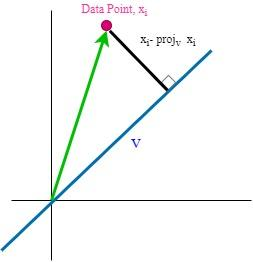

Figure 1.Figure shows the orthogonal distance, ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} -{\textrm{proj}}_{\mathit{\mathbf{v}}} \;{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$, between the line v and data point $x_i \ldotp$

We are given $n$ data points the columns of the matrix **X** contains the data points ranging from 1 to n. We need to find the direction of vector,  $\mathit{\mathbf{v}}$, which reduces the orthogonal distance, $x_{i\;} -{\textrm{proj}}_v \;x_i$, for n data points.  Since we are only interested in the direction of vector, we can safely assume ${\left\|\mathit{\mathbf{v}}\right\|}_2 =1$. This formulated mathematically as,

   
$$\underset{\mathit{\mathbf{v}}}{\textrm{minimize}\;} {\sum_{i=1}^n {\left\|{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} -{\textrm{proj}}_{\mathit{\mathbf{v}}} \;{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \right\|}_{2\;} }$$



$$\textrm{subject}\;\textrm{to}:\;\;{\left\|\mathit{\mathbf{v}}\right\|}_2 =1$$


The above equation can be formulated to form a equaivalent maximization problem shown below, *(for detailed derivation consult Chapter 6 of  Numerical Algorithms by Justin Solomon)*

  
$$\underset{\mathit{\mathbf{v}}}{\mathrm{m}\textrm{axi}\textrm{mize}\;} {\mathit{\mathbf{v}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{X}}\;{\mathit{\mathbf{X}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{v}}$$



$$\textrm{subject}\;\textrm{to}:\;\;{\left\|\mathit{\mathbf{v}}\right\|}_2 =1$$


It can be shown that the eigen vector corresponding to the dominant eigen value, maximises the above equation. The vector $\mathit{\mathbf{v}}$ is known as the principal component of the dataset. It can be computed using the Power Iteration method.

Use your power iteration method written in Question 2 part (a) to compute the dominant eigen vector. You can also use the MATLAB's function eig()  to coompute the eigen vector.

Use the above two approaches and plot the best straight line fit through the data on the same graph. Comment on the results, explain any differences/similarities in both approaches. What is the error being minimized in each case?

load('Data_PCA.mat')


% use x_plot to plot the lines obtained by PCA and regression
x_plot = linspace(-3,3,100); 


% % % % % % % WRITE YOUR CODE HERE % % % % % % %
%% Write code below to approximate the parameter a using the Leastsquares
%% method, and evaluage y_reg = a*x_plot;
%% Wrtoe code below to approximate the parameter a using the PCA
%% method, and evaluage y_PCA = a*x_plot;
[~,v]=power_method(X*X',1e-4);
y_pca = (v(2)/v(1))*x_plot;
M1 = X(1,:)';
M2 = X(2,:)';
M3 = M1'*M1;
a_reg = M3\M1'*M2;
y_reg = a_reg.*x_plot;
%%%%%%%%%%%%%%  PLOTS  %%%%%%%%%%%%%%%%%%%%%%%%%
figure(1)
hold on 
grid on 
plot(x,y,'ro') % plot given data 
plot(x_plot,y_pca)
plot(x_plot,y_reg)
legend('Data','PCA fit', 'Regression')


# Appendix

Write the code for the function here.

Question 2 (a):  

function [eivgen_value,vector]= power_method(A,tol)
% Write you code here
[m,n] = size(A);
v1 = ones(m,1);
v2 = A*v1/(norm(A*v1));
while normest(v2-v1)>tol
   v1=v2;
   v2=A*v1/(norm(A*v1,inf));
end
vector=v2;
eivgen_value=norm(A*v2,inf);
end



Question 2 (b):

function [V,eigen] = simultaneous_orthogonalisation(A,tol)
% eigen is the vector containing Eigen Values
% V is the vector containing Eigen Vectors. 
% Each column of V contains the eigen vectors for a given eigen value.
% Write you code here
[m,n] = size(A);
Q0 = eye(n);
A1 = A*Q0;
[Q1,R] = qr(A1);
while normest(Q1-Q0)>tol
    Q0 = Q1;
    A1 = A*Q0;
    [Q1,R] = qr(A1);
end
V=Q1;
eigen=diag(R);
end


Question 2 (c):

function [V,eigen] = QR_algorithm(A,tol)
% eigen is the vector containing Eigen Values
% V is the vector containing Eigen Vectors. 
% Each column of V contains the eigen vectors for a given eigen value.
% Write you code here

[Q,R] = qr(A);
Qnew = Q;
Rnew = R;
EV = Q;
error = 1;
while error >= tol
    Q = Qnew;
    R = Rnew;
    Anew = R*Q;
    [Qnew,Rnew] = qr(Anew);
    EV = EV*Qnew;
    error = norm(Rnew-R,2);
end
eigen = diag(Rnew*Qnew);
V = EV;
end

You can use the space below to write any additional funcitons if needed.